# Odometry Data

BY MARC GUITART & CATERINA MOLL

G12 - B

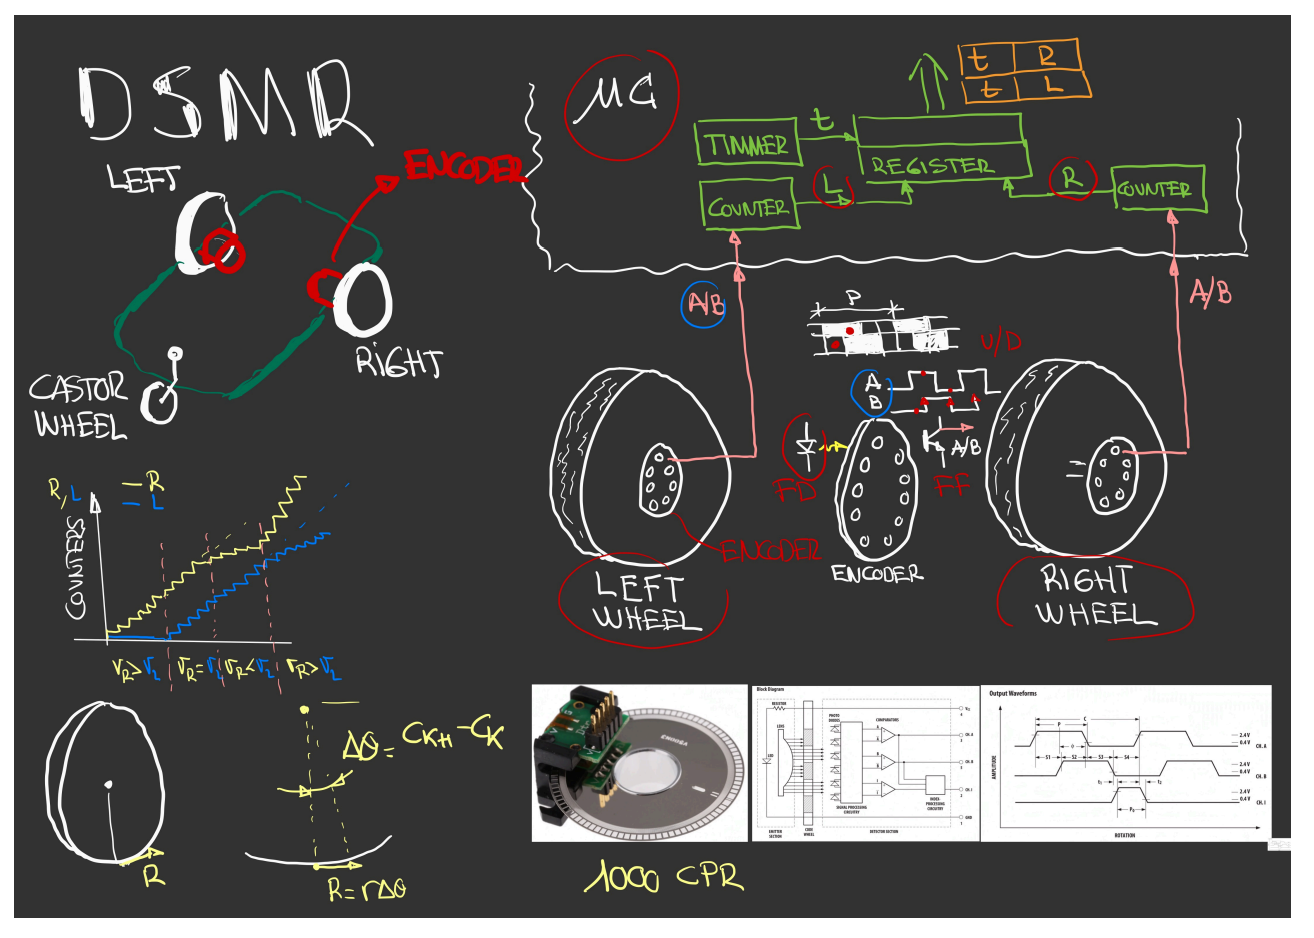

## Load Data

clear
load('Encoder_Data.mat')


R_acu & L_acu: The microcontroller counter report; firts column time stamp, second column the total displacement of right and left wheel in meters. 

R_acu

R_acu =          0         0
    0.0200         0
    0.0400         0
    0.0600         0
    0.0800         0
    0.1000         0
    0.1200         0
    0.1400         0
    0.1600         0
    0.1800         0


L_acu

L_acu =          0         0
    0.0200         0
    0.0400         0
    0.0600         0
    0.0800         0
    0.1000         0
    0.1200         0
    0.1400         0
    0.1600         0
    0.1800         0


Ts & Tf : Sample time and total experiment time (Tf=Numbers of rows *Ts) in [s]

Ts

Ts = 0.0200

Tf

Tf = 60.0800

Tf=length(R_acu(:,2))*Ts

Tf = 60.0800

ts=diff(R_acu(:,1)) % it is constant

ts =     0.0200
    0.0200
    0.0200
    0.0200
    0.0200
    0.0200
    0.0200
    0.0200
    0.0200
    0.0200


r_w & W: Mobile Robot paramenters; wheel radius and distance between wheels in [m]

r_w

r_w = 0.0947

W

W = 0.5200

W % 2S

W = 0.5200

## Visualizing L&R info

t=R_acu(:,1)

t =          0
    0.0200
    0.0400
    0.0600
    0.0800
    0.1000
    0.1200
    0.1400
    0.1600
    0.1800


t=(0:Ts:Tf-Ts)'

t =          0
    0.0200
    0.0400
    0.0600
    0.0800
    0.1000
    0.1200
    0.1400
    0.1600
    0.1800


t=linspace(0,Tf,length(R_acu(:,2)))'

t =          0
    0.0200
    0.0400
    0.0600
    0.0800
    0.1000
    0.1200
    0.1400
    0.1601
    0.1801


`Total wheel displacements profile`

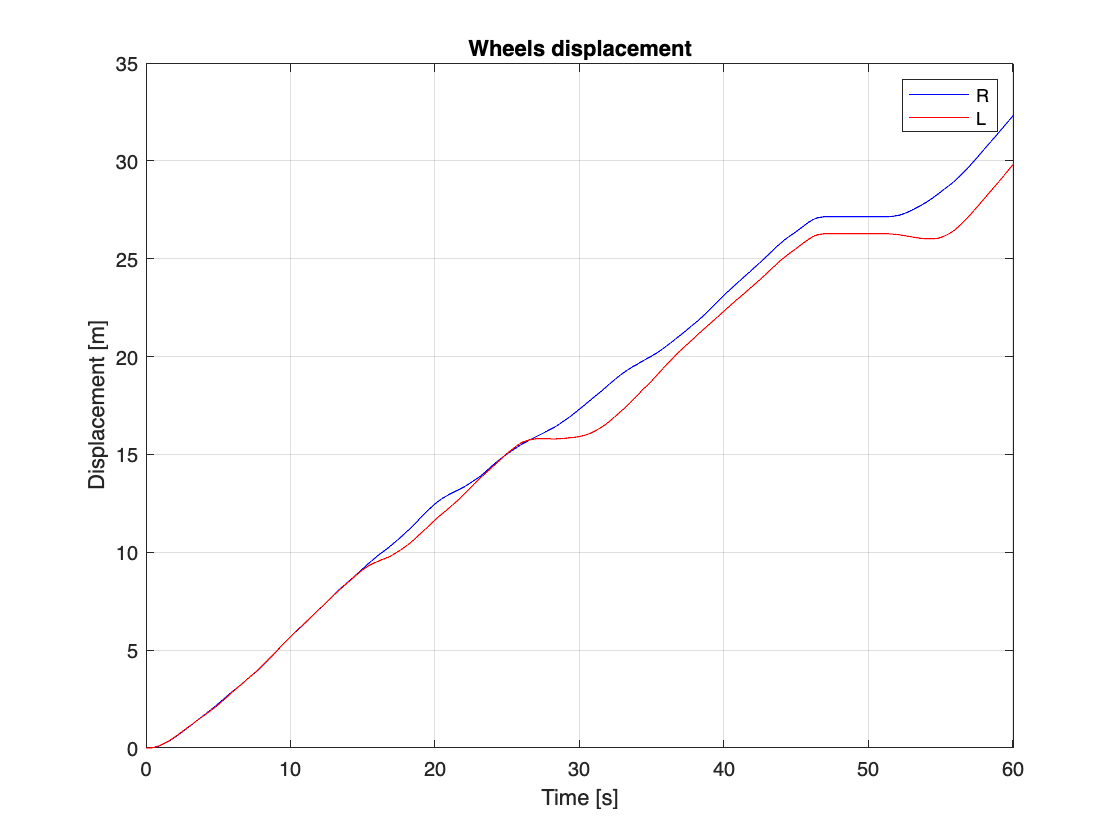

figure
plot(t,R_acu(:,2),'b')
hold on 
plot(t,L_acu(:,2),'r') 
xlim ([0 Tf])
grid on
title('Wheels displacement')
xlabel ('Time [s]')
ylabel ('Displacement [m]')
legend('R','L')

## Wheel incremental displacements

It tell us how much displacement did the wheel during a sample time.

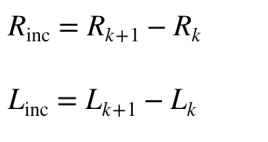

R_inc=diff(R_acu(:,2)) 

R_inc =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


L_inc=diff(L_acu(:,2))

L_inc =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


**Incremental displacements profile**

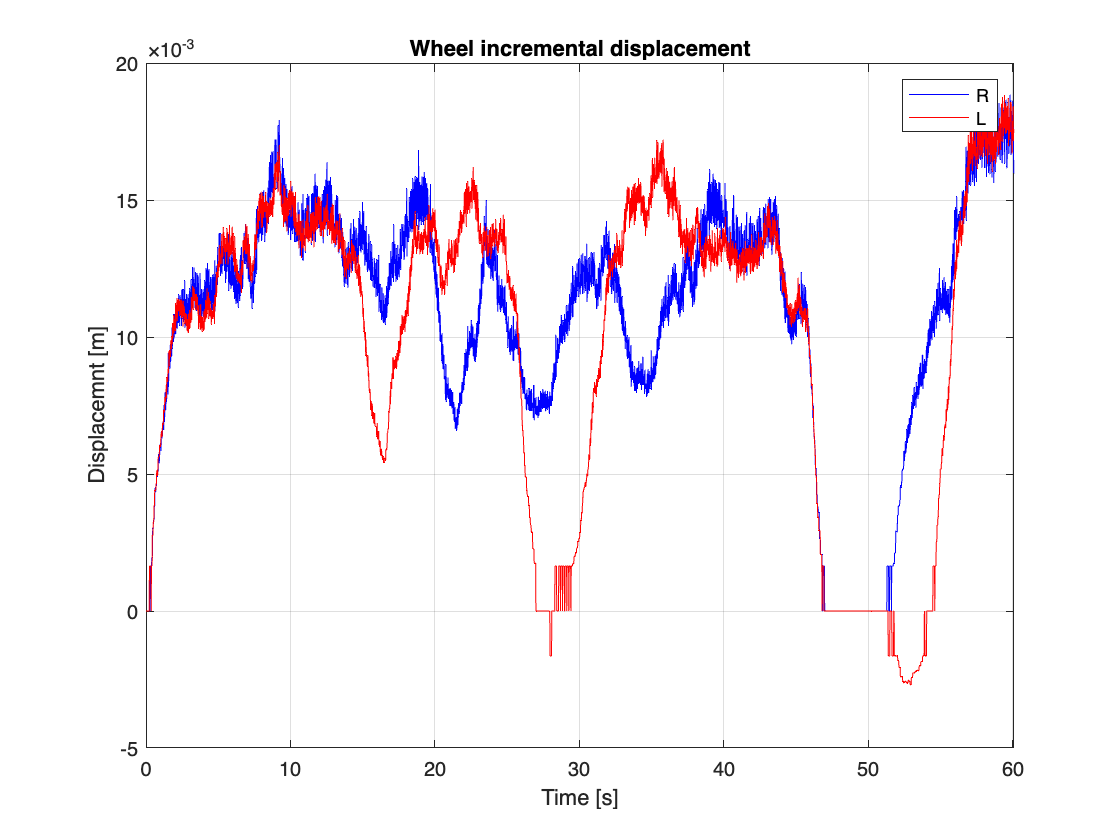

figure
plot(t(1:end-1),R_inc,'b') % We losted one sample with 'diff' command
hold on 
plot(t(1:end-1),L_inc,'r') % We losted one sample with 'diff' command
hold on 
xlim ([0 Tf])
grid on
title('Wheel incremental displacement')
xlabel ('Time [s]')
ylabel ('Displacemnt [m]')
legend('R','L')

## Visualize increment velocity

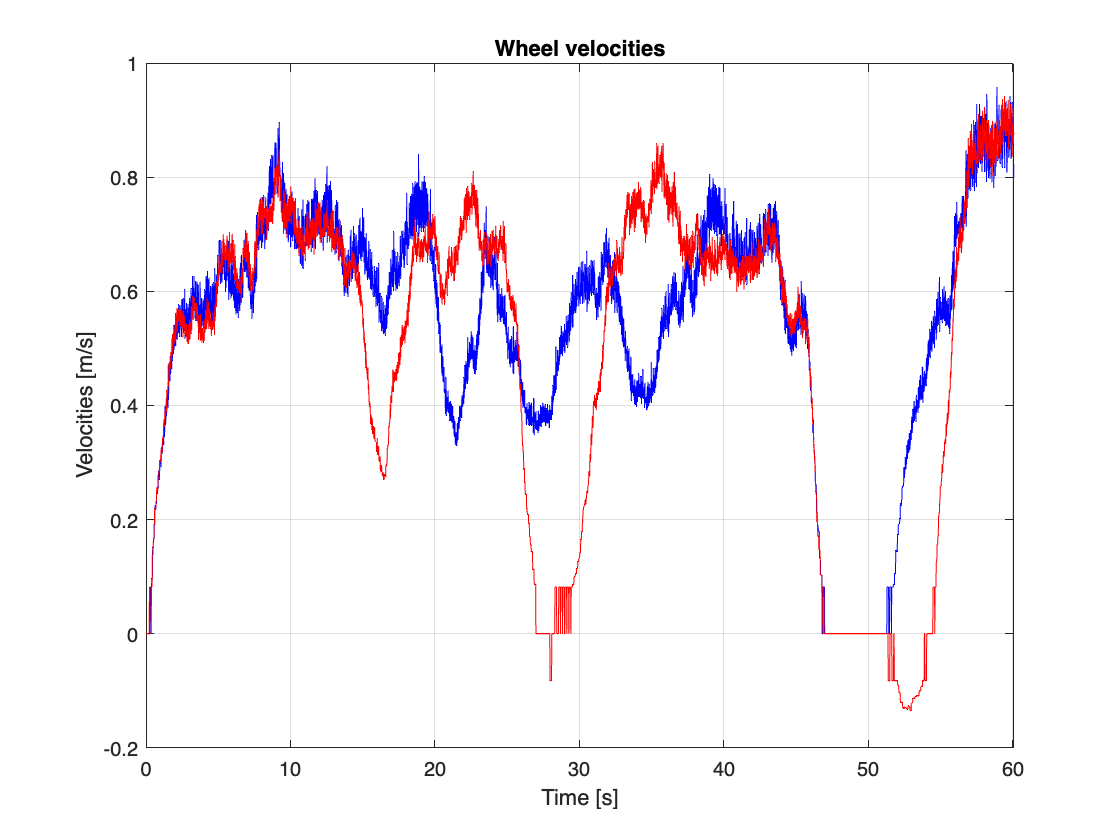

figure
plot(t(1:end-1),R_inc/Ts,'b')
hold on 
plot(t(1:end-1),L_inc/Ts,'r') 
xlim ([0 Tf])
grid on
title('Wheel velocities')
xlabel ('Time [s]')
ylabel ('Velocities [m/s]')

**Equivalence of Encoder Data**

Some time the microcontroller gives wheels increment displacement. To recover total wheel displacement

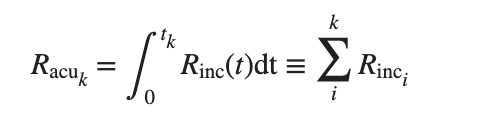

R_ac=cumsum(R_inc,1)

R_ac =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


L_ac=cumsum(L_inc,1)

L_ac =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


**Recovered wheel displacements profile**

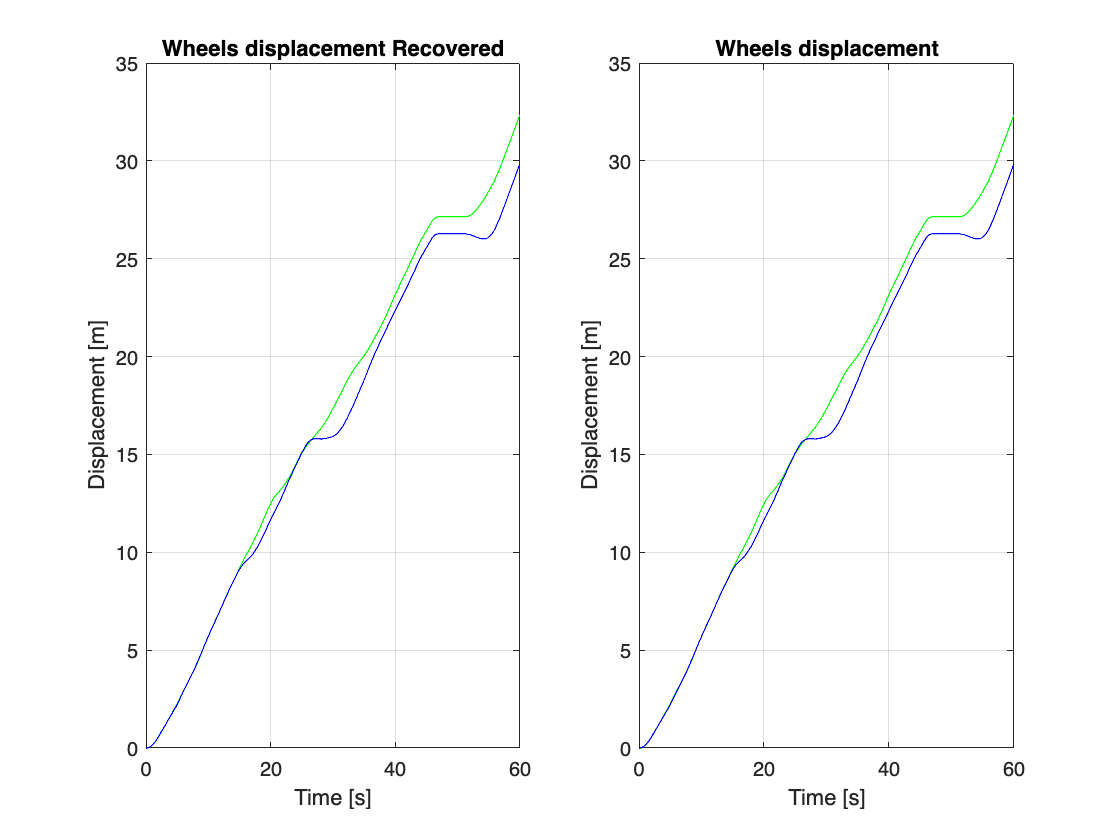

figure
subplot(1,2,1)
plot(t(1:end-1),R_ac,'g')
hold on 
plot(t(1:end-1),L_ac,'b') 
xlim ([0 Tf])
grid on
title('Wheels displacement Recovered')
xlabel ('Time [s]')
ylabel ('Displacement [m]')
subplot(1,2,2)
plot(t,R_acu(:,2),'g')
hold on
plot(t,L_acu(:,2),'b')
xlim ([0 Tf])
grid on
title('Wheels displacement')
xlabel ('Time [s]')
ylabel ('Displacement [m]')

## Odometry

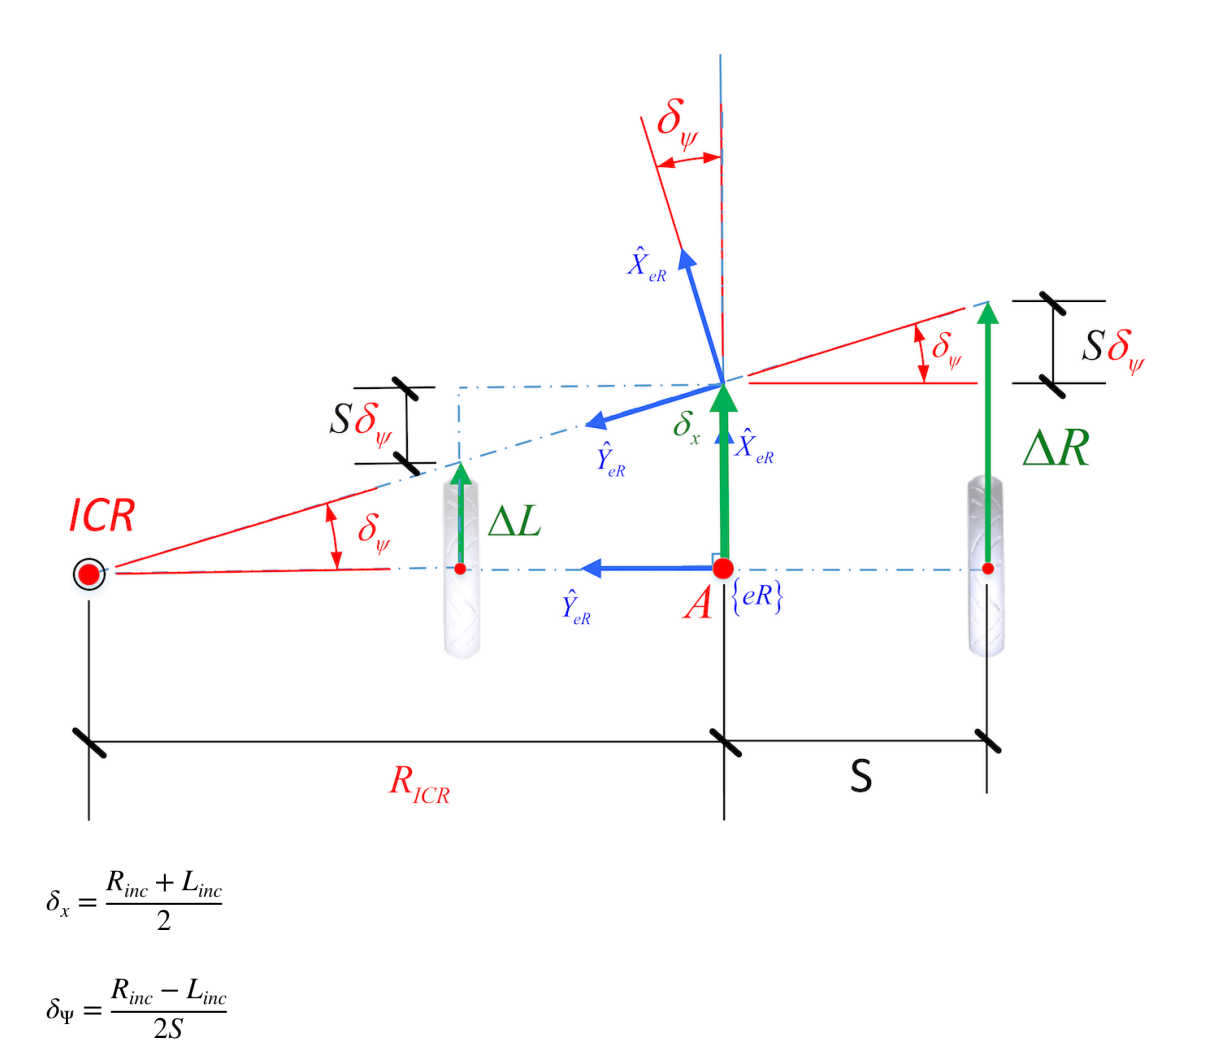

Compute $\delta_x$ and $\delta_{\psi }$

delta_x= (R_inc+L_inc)/2

delta_x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


delta_psi= (R_inc-L_inc)/W

delta_psi =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


## Pose integration

Compare your results

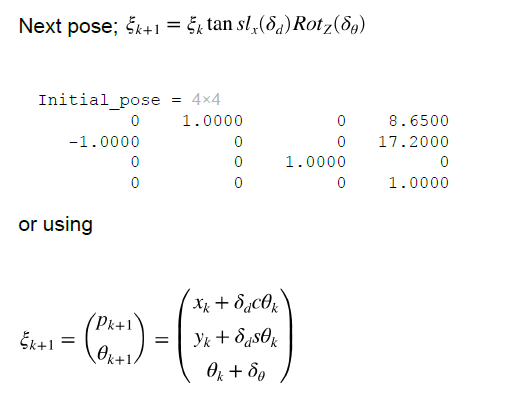

Initial_pose=transl(8.65,17.2,0)*trotz(-pi/2) %pi/2 = 1.5707

Initial_pose =          0    1.0000         0    8.6500
   -1.0000         0         0   17.2000
         0         0    1.0000         0
         0         0         0    1.0000


Pose(:,:,1)=Initial_pose;
for i=1:length(t)-1
    Pose(:,:,i+1)=Pose(:,:,i)*transl(delta_x(i),0,0)*trotz(delta_psi(i));
    Position(:,i+1)=transl(Pose(:,:,i));
    Orientation(:,i+1)=tr2rpy(Pose(:,:,i));
 end


or using 

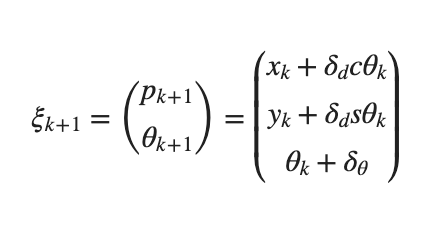

  Initial_position=transl(Initial_pose)

Initial_position =     8.6500
   17.2000
         0


 Initial_orientation=-pi/2

Initial_orientation = -1.5708

 x(1)=Initial_position(1)+0.05 % for comparing reasons we offset x by 5cm

x = 8.7000

 y(1)=Initial_position(2)

y = 17.2000

 o(1)=Initial_orientation

o = -1.5708

 for i=1:(length(t)-1)
    x(i+1)= x(i)+delta_x(i)*cos(o(i));
    y(i+1)= y(i)+delta_x(i)*sin(o(i));
    o(i+1)=o(i)+delta_psi(i);
 end


Displaying trajectory

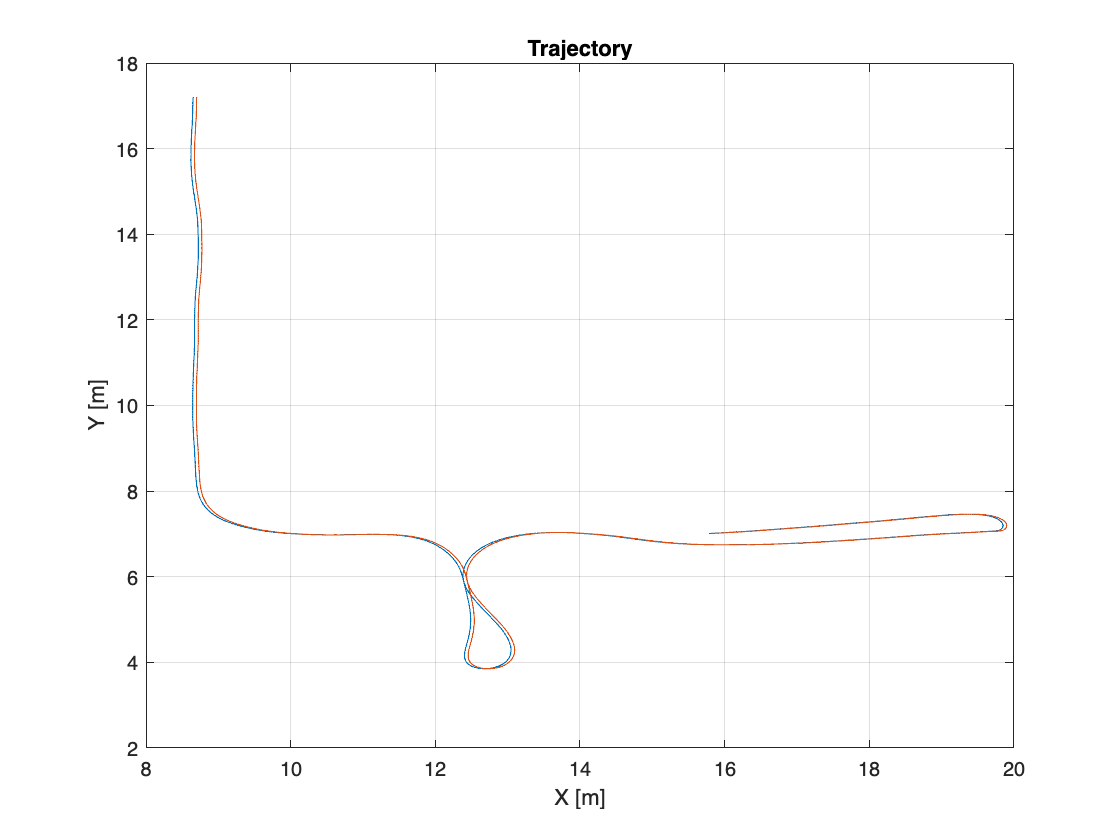

 figure
plot(Position(1,2:end),Position(2,2:end))
grid on
hold on
title('Trajectory')
xlabel ('X [m]')
ylabel ('Y [m]')
plot(x,y)

Understanding Orientation

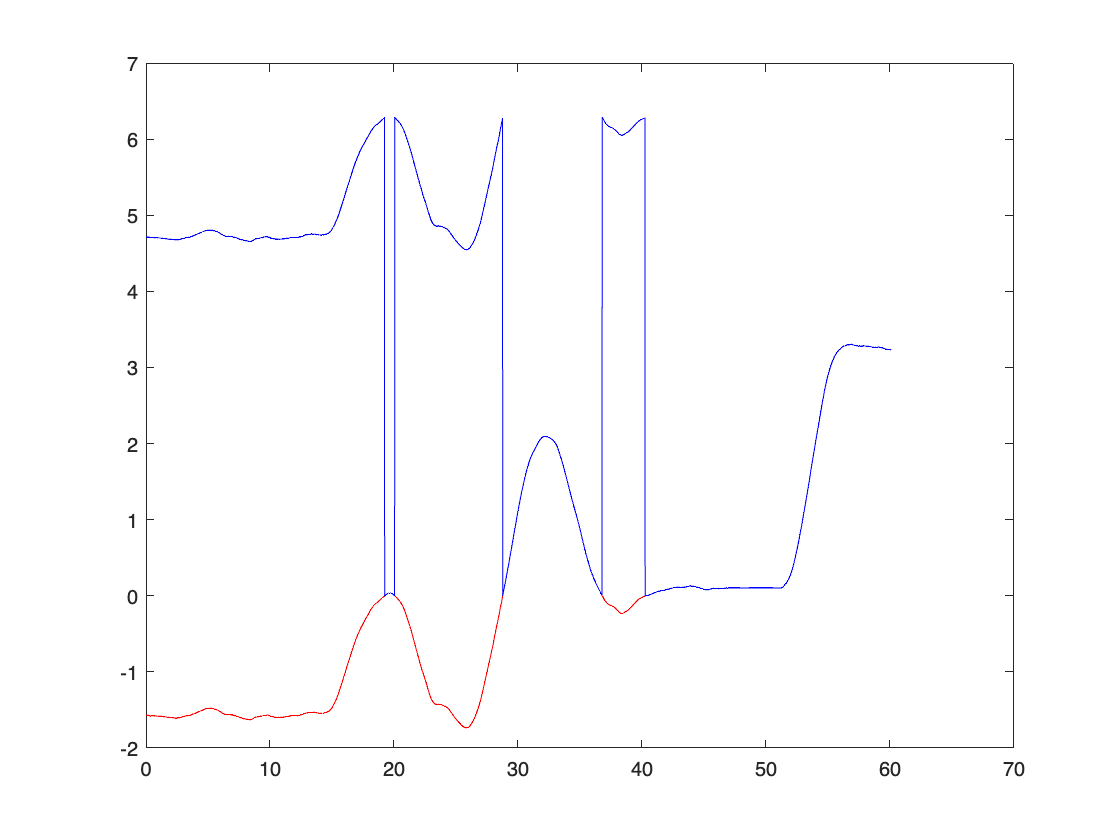

figure
plot(t,o,'r')
hold on
plot(t,mod(o,2*pi),'b')

Plotting the enviroment and trajectory

figure1=figure

figure1 =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 278 560 420]
       Units: 'pixels'

  Show all properties


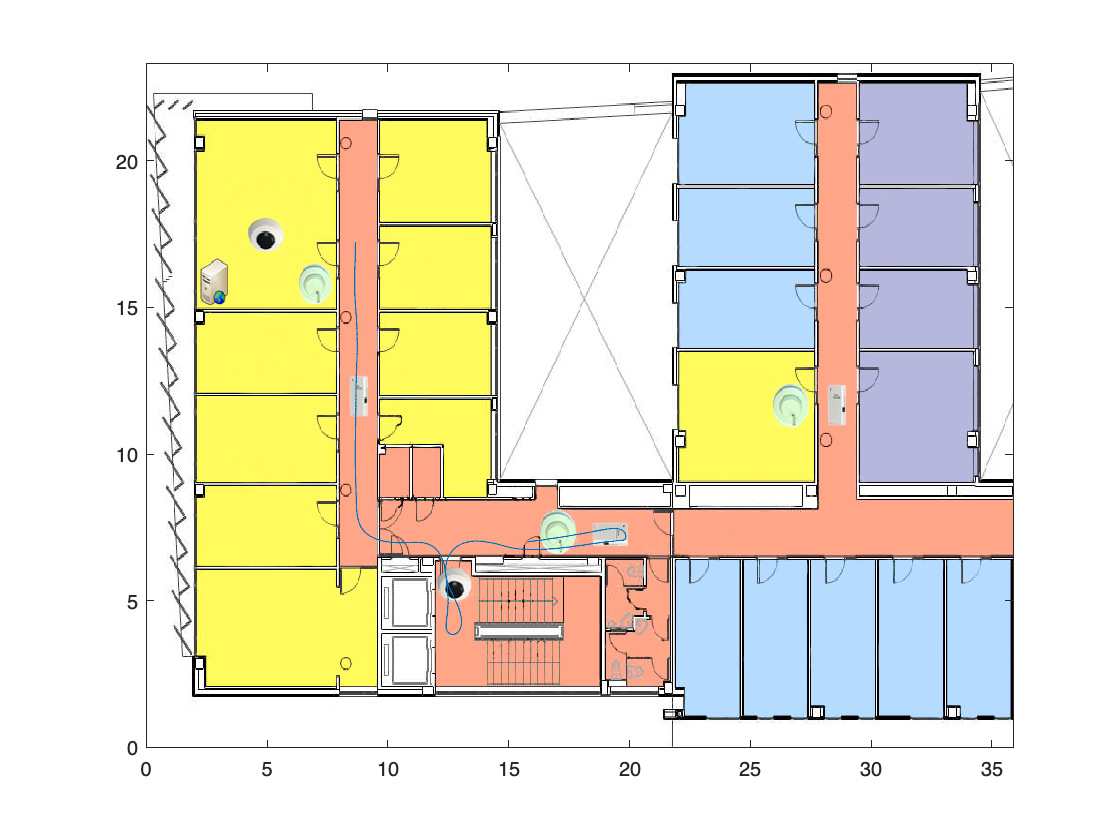

I=imread('Enviroment.png');
x_ima=[0 35.9];
y_ima=[23.31 0];
image(I,'XData',x_ima,'YData',y_ima);
axis xy
hold on
plot(Position(1,2:end),Position(2,2:end))

Uncertanty: Adding noise

Noise in the odometry displacement

 delta_x_n=((R_inc+L_inc)/2)+randn((length(t)-1),1)*0.005

delta_x_n =     0.0027
    0.0092
   -0.0113
    0.0043
    0.0016
   -0.0065
   -0.0022
    0.0017
    0.0179
    0.0138


Noise in the odometry change of orientation

 delta_psi_n=((R_inc-L_inc)/W)+randn((length(t)-1),1)*0.005 

delta_psi_n =     0.0077
   -0.0031
   -0.0035
   -0.0071
   -0.0005
   -0.0005
   -0.0016
   -0.0042
   -0.0083
    0.0151


Displacement noise visualization

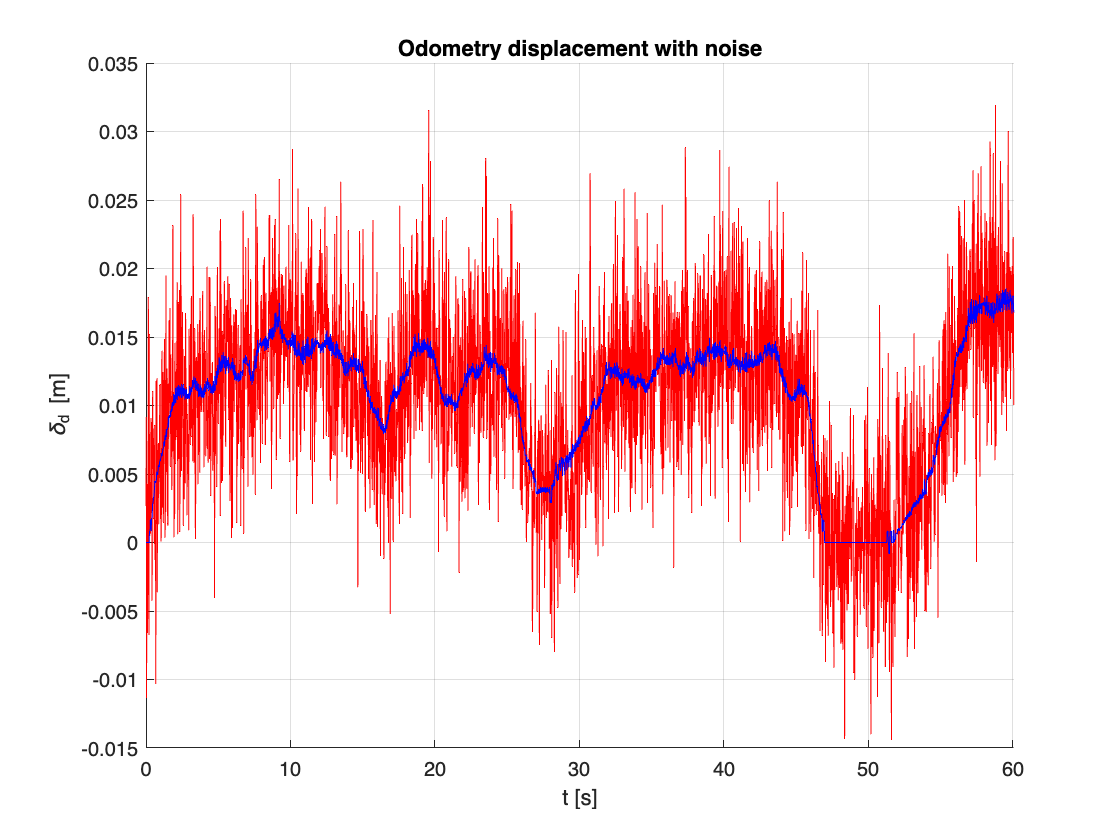

figure
hold on
plot(t(1:end-1),delta_x_n,'r')
xlim ([0 Tf])
grid on
title('Odometry displacement with noise')
xlabel ('t [s]')
ylabel ('\delta_d [m]')
plot(t(1:end-1),delta_x,'b')

Orientation noise visualization

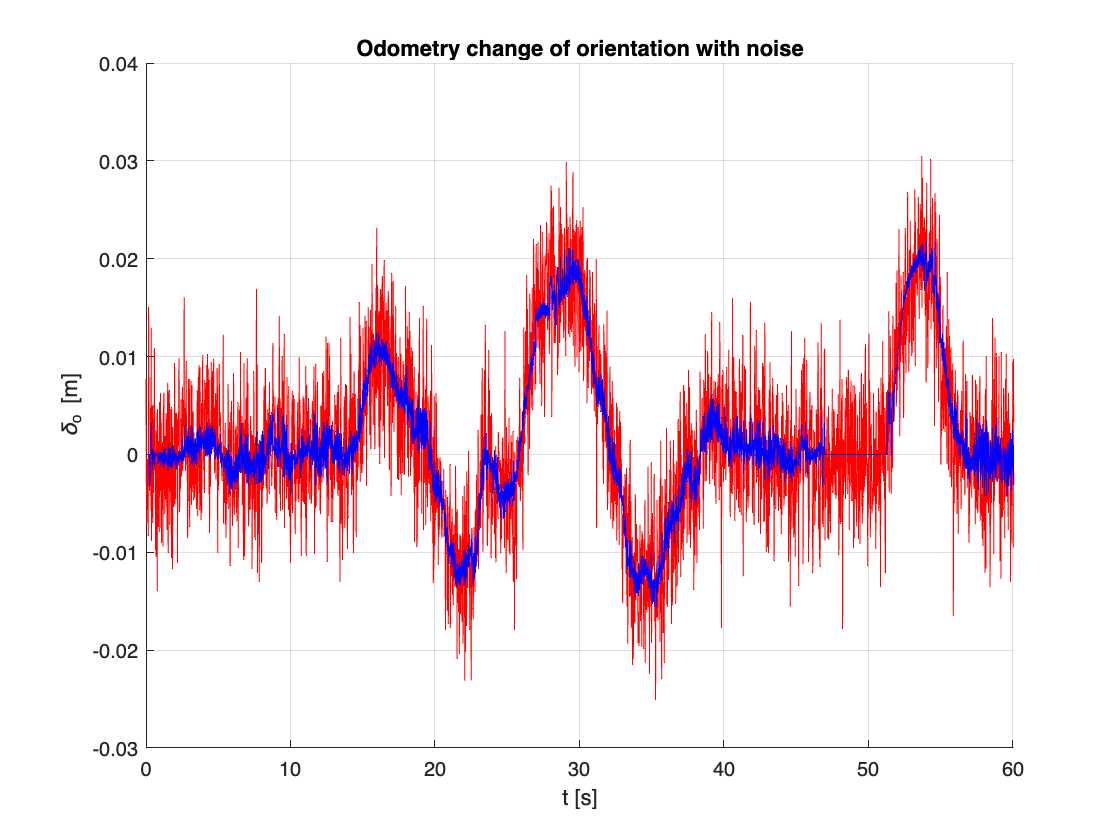

figure
hold on
plot(t(1:end-1),delta_psi_n,'r')
xlim ([0 Tf])
grid on
title('Odometry change of orientation with noise')
xlabel ('t [s]')
ylabel ('\delta_o [m]')
plot(t(1:end-1),delta_psi,'b')

## Pose integration with noise



Initial_pose=transl(8.65,17.2,0)*trotz(-pi/2)

Initial_pose =          0    1.0000         0    8.6500
   -1.0000         0         0   17.2000
         0         0    1.0000         0
         0         0         0    1.0000


x_res2 = zeros(length(L_inc), 1)

x_res2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


y_res2 = zeros(length(L_inc), 1)

y_res2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



for i=1:length(L_inc)
    Initial_pose = Initial_pose*transl(delta_x(i),0,0)*trotz(delta_psi(i));
 
    x_res2(i)=Initial_pose(1, 4)
    y_res2(i)=Initial_pose(2, 4);
 end

x_res2 =     8.6500
         0
         0
         0
         0
         0
         0
         0
         0
         0


x_res2 =     8.6500
    8.6500
         0
         0
         0
         0
         0
         0
         0
         0


x_res2 =     8.6500
    8.6500
    8.6500
         0
         0
         0
         0
         0
         0
         0


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
         0
         0
         0
         0
         0
         0


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
         0
         0
         0
         0
         0


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
         0
         0
         0
         0


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
         0
         0
         0


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
         0
         0


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
         0


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 =     8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


x_res2 = 3003×1
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500
    8.6500


## Comparing  trajectories

 figure
 plot(Position_n(1,2:end),Position_n(2,2:end),'r')
 hold on
 plot(Position(1,2:end),Position_n(2,2:end),'b')

## Ellipse error

It is of interest to launch many time the dices (our trajectory with noise) and check for the last position and orientation 

 Initial_pose=transl(8.65,17.2,0)*trotz(-pi/2)
 Pose_n(:,:,1)=Initial_pose;
 for j=1:1000
     delta_x_n=((R_inc+L_inc)/2)+randn((length(t)-1),1)*0.005; 
     delta_psi_n=((R_inc-L_inc)/W)+randn((length(t)-1),1)*0.005; 
     for i=1:length(t)-1
         Pose_n(:,:,i+1)=Pose_n(:,:,i)*transl(delta_x_n(i),0,0)*trotz(delta_psi_n(i));
         Position_n(:,i+1)=transl(Pose_n(:,:,i));
         Orientation_n(:,i+1)=tr2rpy(Pose_n(:,:,i));
     end
     Positions_n(:,j)=Position_n(:,end);
     Orientations_n(:,j)=Orientation_n(:,end);
 end

**Visualizing the experimental ellipse error of final position**

 figure
 scatter(Positions_n(1,:),Positions_n(2,:))
